# 静态宽带快照成像光谱仪定位和光谱提取


clear;
clc;
close;


## 初始参数

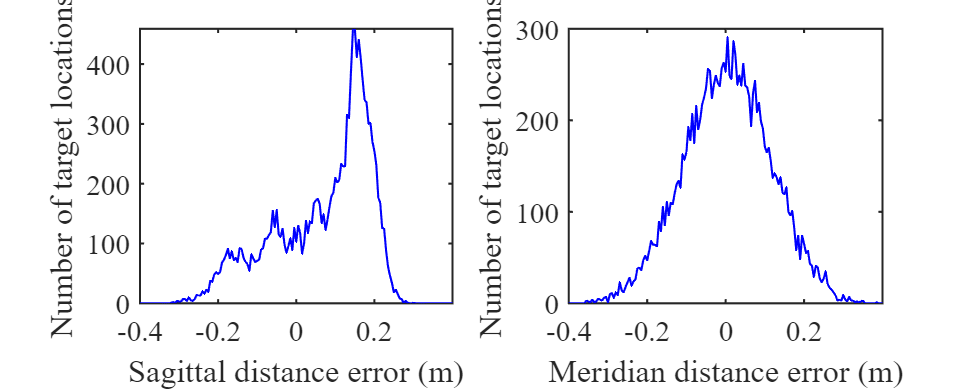


    [f1, f2, f3, d, D1, a1, a2, a3, a4, n, n1, n2, n3, n4, bo1, bo2, bo3, ... 
     b_jg1, b_jg2, M, r, a_bs, sp_size, sp1_size] = F_start();
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%5
%     aa_s = atan(f1*tan(-5*pi/180) / f2);    %弧矢面目镜出射角度
%     aa_m = atan(f1*tan(0*pi/180) / f2);
%     [xia, yia] = F_bo_wei(aa_s, aa_m, f3, n1, n2, n3, n4, a1, a2, a3, a4)
% 

    

    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

    
    
    det_nl1 = -1;    % 探测模块 判断某帧数据前是否有数据
    
%     定标角度
%     [x_a, y_a] = F_match_anglex(a_bs, f1, f2, f3, n1, n2, n3, n4,  ...
%                  a1, a2, a3, a4, M, d, bo1, bo2, b_jg1, b_jg2, sp1_size);   %粗定标角度（度）
%     save T1 x_a y_a;
    load T1.mat; 
  
%     [x_a_YH, y_a_YH] = F_YH_match_anglex(a_bs, f1, f2, f3, n1,n2, n3, n4, ...
%         a1, a2, a3, a4, M, d, bo1, bo2, b_jg1, b_jg2, sp1_size);   %细定标角度（度）
%     
%     save T_YH x_a_YH y_a_YH;
    load T_YH.mat; 
% 
%     [x1_a_YH, y1_a_YH] = F_YH1_match_anglex(a_bs, f1, f2, f3, n1,n2, n3, n4, ...
%         a1, a2, a3, a4, M, d, bo1, bo2, b_jg1, b_jg2, sp1_size);   %细定标角度（度）
    
%     [A_YH] = F_YH2_match_anglex(f1, f2, f3, n1, n2, n3, n4, ...
%                     a1, a2, a3, a4, bo1, bo2, b_jg1, b_jg2, sp1_size);
%     save A_YH A_YH;
    load A_YH.mat; 
% [errx, erry] = F_errorFigure(A_YH, x_a, y_a, x_a_YH, y_a_YH);
% save err3 errx erry;
load err3.mat;
Figure_err(errx, erry);

## 仿真数据获取（忽略像差并对衍射进行简化）

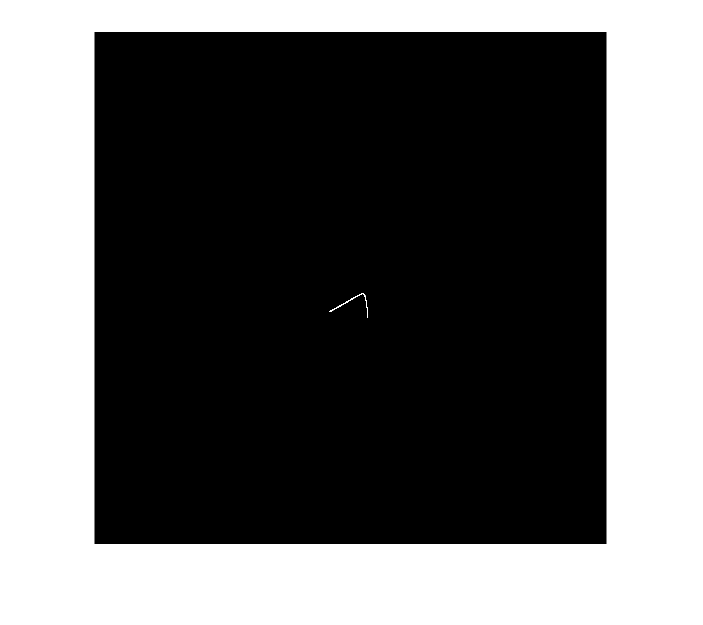

    det_nl1 = -1;    % 探测模块 判断某帧数据前是否有数据

    %探测器模板像素亮度值(a_s = a_m = 0)

    %目标物方位角
    %          ,{6, 4,  2,0, -2, -4, -6},{5, 3,  1, -1, -3, -5},,{0, 0,  0,0, 0, 0, 0}
    x = {{0}
%         {3, -3, 0, 0, 4.2426, 4.2426, -4.2426, -4.2426, 0} ...
%         {-5, -3,  -1, 1, 3, 5}
        };
    y = {{0}
%         {0, 0, 3, -3, 4.2426, -4.2426, 4.2426, -4.2426, 0}...
%         {5, 3,  1, -1, -3, -5}
        };

    %目标物原始光谱能量
%     [sp_nl] = F_sp_nl(ones(1, sp_size));
%     sp1_nl = F_sp_nl(ones(1, sp_size), sp_size, sp1_size, b_jg1, b_jg2);
%     sp2_nl = F_sp_nl(ones(1, sp_size), sp_size, sp1_size, b_jg1, b_jg2);
%     sp3_nl = F_sp_nl(zeros(1, sp_size), sp_size, sp1_size, b_jg1, b_jg2);

%     [sp1_nl, sp1_nlys] = F_make_sp(ones(1, sp_size)*0.2, n, sp_size, sp1_size, b_jg1, b_jg2);
%     save sp sp1_nl sp1_nlys;
    load sp.mat;
%     [errArray] = F_spErrorFigure(A_YH, x_a, y_a, x_a_YH, y_a_YH, sp1_nl);
%     save spErrArray1 errArray;
%     load spErrArray1.mat;

%     save spErrArray errArray;
%     load spErrArray.mat;
%     Figure_spErr(0 : 0.0005 : 0.1, errArray);
%     sp2_nl = F_make_sp(ones(1, sp_size)*0.2, n, sp_size, sp1_size, b_jg1, b_jg2);
    sp_nl = {%{sp1_nl}
        {sp1_nl, sp1_nl, sp1_nl,sp1_nl,  sp1_nl,sp1_nl, sp1_nl, sp1_nl, sp1_nl}...
%         ,{sp2_nl, sp2_nl,sp2_nl,  sp2_nl,sp2_nl, sp2_nl, sp2_nl}
        };
%     Figure_sp(sp1_nlys, n);
    
    % 仿真探测器数据
    
    tt = 0;
    [~, M_tt] = size(x);    %共有多少帧数据
    det0 = cell(1,M_tt);     % 探测数据容器
    while tt < M_tt
        tt = tt + 1;
%         [det, det_tem1] = Fdata4(x{tt}, y{tt}, sp_nl{tt}, f1, f2, f3, n1, n2, n3, n4, ...
%                         a1, a2, a3, a4, r, d, M);
        [det, det_tem1] = F_YH_data4(x{tt}, y{tt}, sp_nl{tt}, f1, f2, f3, n1, n2, n3, n4, ...
                        a1, a2, a3, a4, r, d, M);
        det0{tt} = det;
    end
%     Figure_3(x{tt}, y{tt}, sp_nl{tt}, f1, f2, f3, n1, n2, n3, n4, ...
%                         a1, a2, a3, a4, r, 0.1*d, M);
     imshow(det);

## 目标探测

% 目标信息容器
a_xy = cell(1, M_tt);   % 目标角度信息
sp_cell = cell(1, M_tt); % 目标光谱信息

tt = 0;
while tt < M_tt
    close all;  % 关闭上一帧目标的特征光谱图
    tt = tt + 1;
    det1 = det0{tt};
    % 1 数据处理和归一化
    gui = 1;
    det_nl2 = Fprocessing(det1, gui);
    
    % 2 能量检测
    if det_nl1 == -1, det_nl1 = zeros(size(det1)); end
    nl_sum = 0;
    wc = 0;
    while wc < M
        wc = wc + 1;

        nc = 0;
        while nc < M 
            nc = nc + 1;
            nl_sum = nl_sum + abs(det_nl2(wc, nc) - det_nl1(wc, nc));
        end
    end

    det_nl1 = det_nl2;

## 确定以下模块是否运行


    fwj1 = 1;   % 粗精度方位角模块是否运行  1 运行， 其他 不运行
    fwj2 = 1;    % 细精度方位角模块是否运行  1 运行， 其他 不运行
    gp = 1;     % 光谱提取模块是否运行  1 运行， 其他 不运行

    % 确定当前帧数据是否存在目标
    if sum(sum(det1)) < 20
        fwj1 = 0;   
        fwj2 = 0;    
        gp = 0;  
    end





## 确定方位角

    
    if nl_sum > 20 && fwj1 == 1
        %处理数据
        det_1 = Fprocessing(det1, 0);
        % det_2 = Fprocessing(det1, 0);
        
        %识别V形图  或 匹配图片 和 获取角度
        
        
        [N_s0, N_m0, x_da0, y_da0, det_2] = Fmatch_1(det_1, x_a, y_a);
        
    end







## 目标优化识别


    if nl_sum > 20 && fwj2 == 1
        %处理数据
%         det_1 = Fprocessing(det1, 0);

        
%         [N_s1, N_m1, x_da, y_da, xx_1, yy_1, det_1] ... 
%             = F_YH_match_1(det_1, det1, x_a_YH, y_a_YH, d);

%         [N_s1, N_m1, x_da, y_da, xx_1, yy_1, xx_2, yy_2] = F_YH_match_2(det1, x_a_YH, y_a_YH,...
%                     x_da0, y_da0, N_s0, N_m0, f1, f2, f3, n1, n2, n3, n4, a1, a2, a3, a4,...
%                     r, d, M,sp_size, sp1_size,bo1,bo2,b_jg1,b_jg2);

        [N_s1, N_m1, x_da, y_da, xx_1, yy_1, xx_2, yy_2] = F_YH_match_3(det1, A_YH, x_da0, y_da0, ...
                        N_s0, N_m0, f1, f2, f3, n1, n2, n3, n4, a1, a2, a3, a4,...
                        r, d, M,sp_size, sp1_size,bo1,bo2,b_jg1,b_jg2 );


    end


## 光谱提取

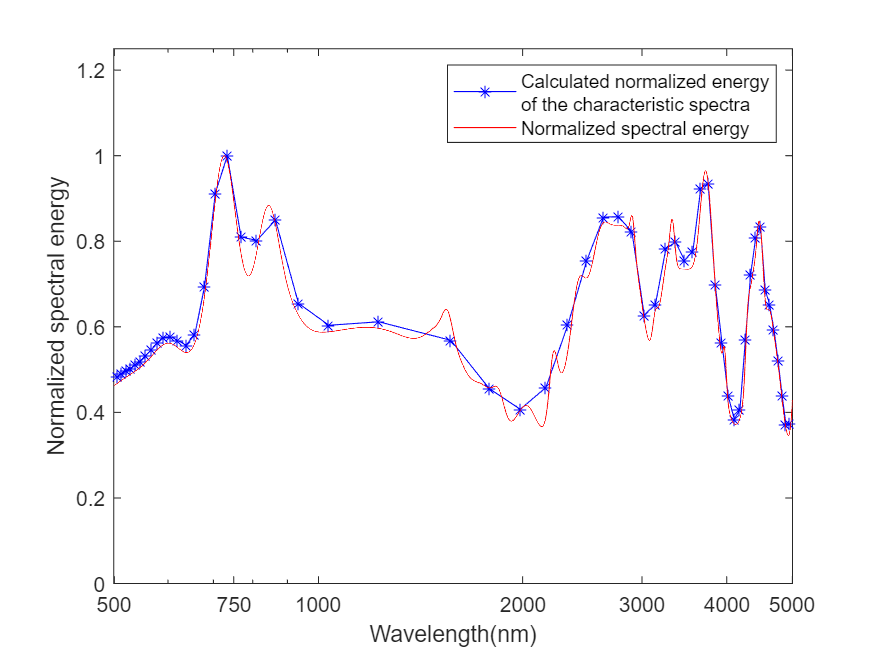


    if nl_sum > 20 && gp == 1 &&  fwj2 == 1
        % 3.1 读取探测器左右臂数据
        [sp0] = F_read_detyb(det1, x_da, xx_1, yy_1);
        [sp1] = F_read_detzb(sp0, det1, x_da, xx_2, yy_2);
        
        % 3.2 计算特征光谱
%         x_da(1,1) = 0; y_da(1,1) = 5;
%         [sp_zb, sp_kd] = F_sp_wzku(sp, d, b_jg1, b_jg2, sp1_size, sp_size, ...
%                          x_da, y_da, f1, f2, f3, n1, n2, n3, n4, a1, a2, a3, a4);

        [sp_zb, sp_kd, sp] = FYH_sp_wzku(sp0, sp1, d, bo2, b_jg1, b_jg2, sp1_size, sp_size, x_da, y_da, ...
            f1, f2, f3, n1, n2, n3, n4, a1, a2, a3, a4);

        

        
        % 3.3 匹配数据和打印 (去掉第一个和最后一个元素)

%         [sp_sp] = F_print(sp, sp0, sp_zb, sp_kd, sp_nl{tt}, x_da, y_da, ...
%             bo1, bo2, bo3, b_jg1, b_jg2, sp1_size);
        [sp_sp, sp_spNoSave] = F_print(sp, sp0, sp_zb, sp_kd, sp_nl{tt}, x_da, ...
            y_da, sp1_size, b_jg1, b_jg2, n);
        % 舍去sp0最后一个元素
%         save sp sp_sp sp_zb;
        [err] = Sp_err(sp_zb(1, :), sp_spNoSave(1, :), sp_nl{1}{1}, bo1, bo2, b_jg1, b_jg2);
        % 3.4 保存数据

        [a_xy, sp_cell] = F_save(x_da, y_da, sp_sp, sp_zb, tt, a_xy, sp_cell);

    end
end

% save sp.mat a_xy sp_cell;
